[t,x] = ode45(@system_ex,0:1:1000,[.8543,.137, .00874])

t =      0
     1
     2
     3
     4
     5
     6
     7
     8
     9


x =     0.8543    0.1370    0.0087
    0.8269    0.1623    0.0109
    0.7967    0.1902    0.0131
    0.7641    0.2204    0.0154
    0.7299    0.2522    0.0180
    0.6947    0.2847    0.0206
    0.6595    0.3172    0.0233
    0.6253    0.3487    0.0260
    0.5928    0.3785    0.0287
    0.5628    0.4060    0.0312


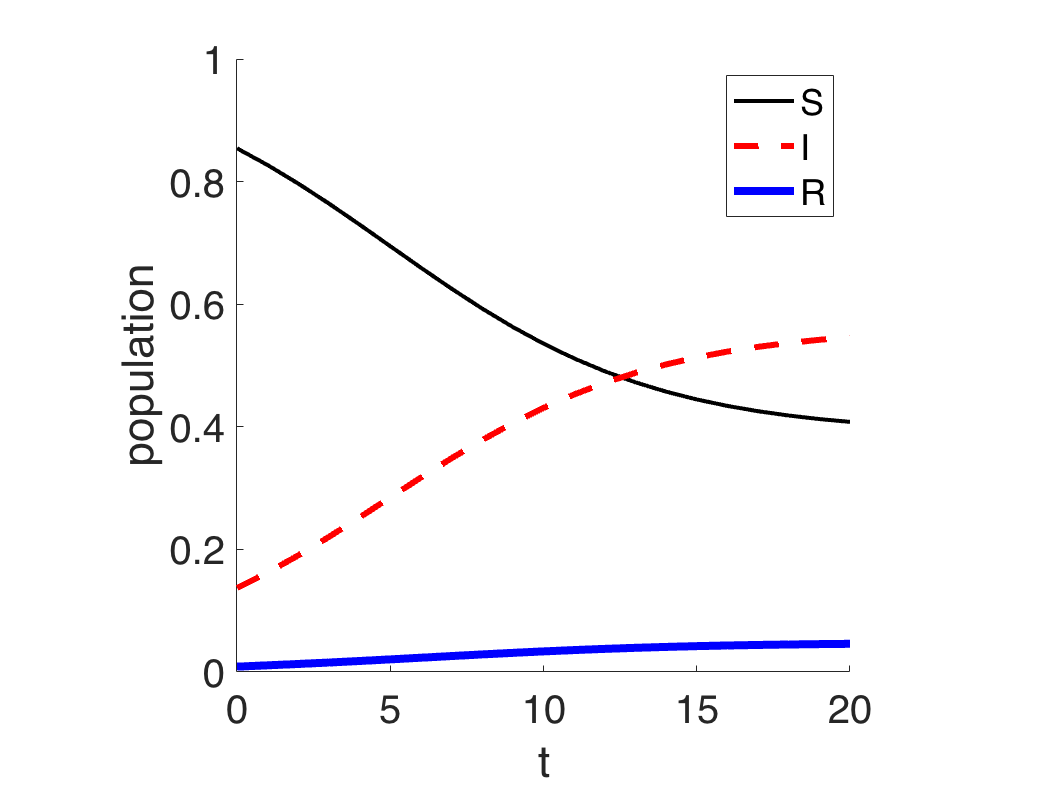

%use Matlab ode solver: https://www.mathworks.com/help/matlab/ref/ode45.html
%plot the numerical solutions x_1(t) and x_2(t) vs. t
figure
axes('Fontsize',20)
hold all
axis square

plot(t,x(:,1),'-k','Linewidth',2)
plot(t,x(:,2),'--r','Linewidth',3)
plot(t,x(:,3),'-b','Linewidth',4)
legend('S','I','R')

xlim([0 20])
ylim([0 1])
xlabel('t')
ylabel('population')

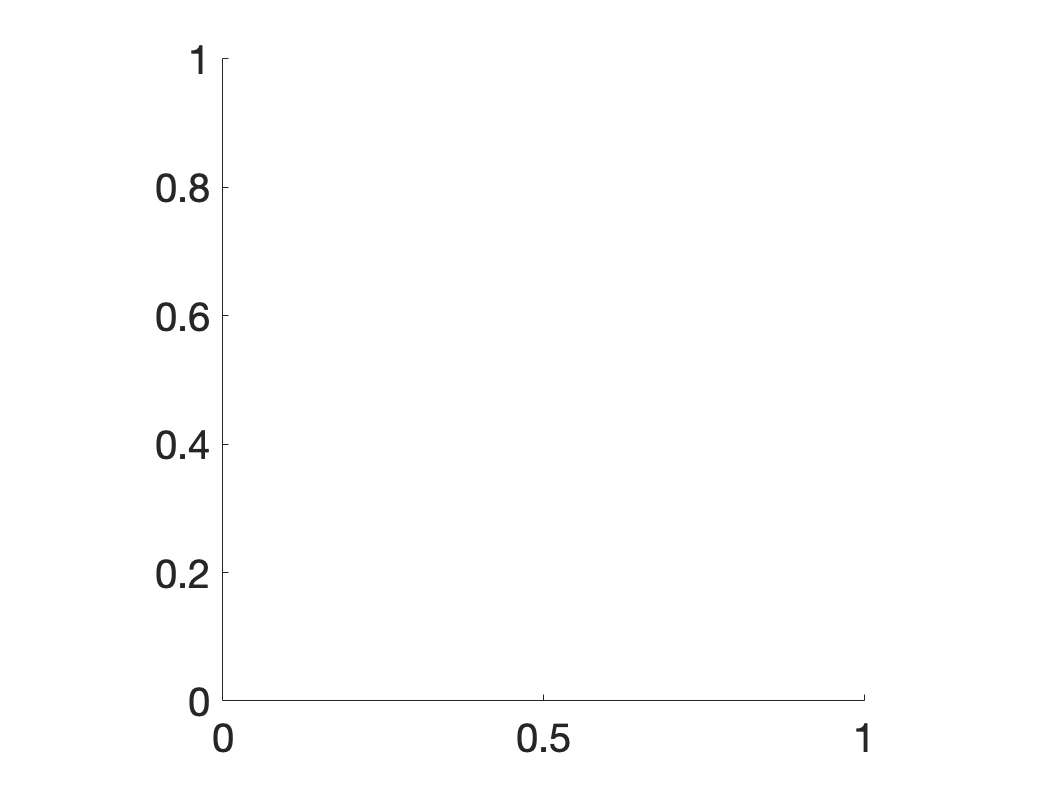


figure
axes('Fontsize',20)
hold all
axis square

function xprime = system_ex(t, x)
    
lambda = .00659;
b = 0.8;
N = 1;
mu = 0.143;
r = .576; %roe
p = .0619; %phi
 
xprime = zeros(3 ,1);

xprime(1) = mu*N-((b*x(2)*x(1))/N)+lambda*x(3)-mu*x(1); 
xprime(2) = ((b*x(2)*x(1))/N)+r*x(3)-(p+mu)*x(2);
xprime(3)= p*x(2)-(r+mu+lambda)*x(3);

end
